x_init = 0.19;
out = sim('model_refrigeration_test');

mass = cell(3,1);
mass{1} = out.simlog.Compressor_Foundation.Pipe_2P.mass.series.values('kg');
mass{2} = out.simlog.System_Level_Condenser_Evaporator_2P_MA.two_phase_fluid_1.mass.series.values('kg');
mass{3} = out.simlog.System_Level_Condenser_Evaporator_2P_TL.two_phase_fluid_1.mass.series.values('kg');

mass_total = mass{1} + mass{2} + mass{3};
time = out.tout;

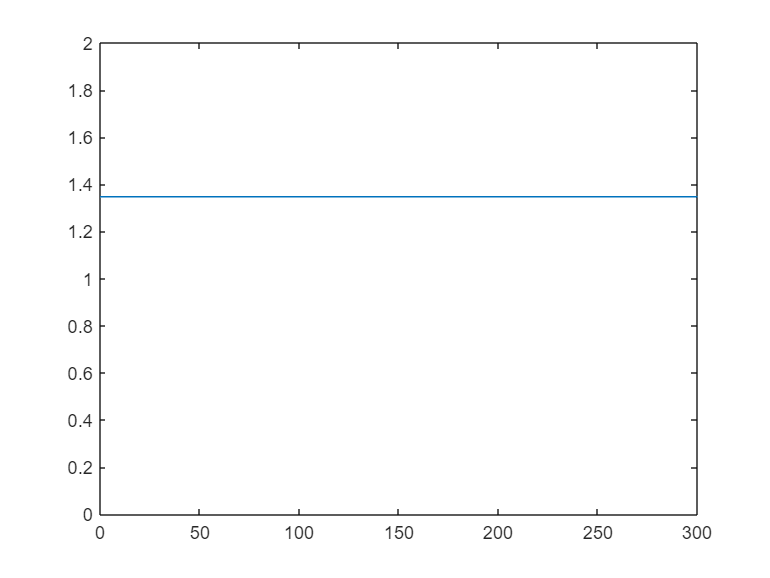

plot(time,mass_total)
ylim([0,2])

mass_end = mass_total(end)

mass_end = 1.3470

rho = mass_end/0.002

rho = 673.4992